Task1

1a

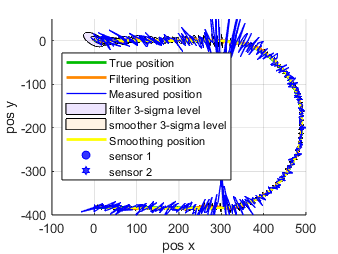

close all;
clear all;
clc
%initialize
%sample time
T = 0.1;
%sample numbers
K = 600;
%CT motion turn model
omega = zeros(1,K+1);
omega(150:450) = -pi/301/T;
x0 = [0 0 20 0 omega(1)]';
%initial value
X = zeros(length(x0),K+1);
X(:,1) = x0;
%true state
for i = 2:K+1
    X(:,i) = coordinatedTurnMotion(X(:,i-1),T);
    X(5,i) = omega(i);
end
%tuning parameter from previous task
sigma_v = 0.01;
sigma_w = pi/180;

x_0 = [0 0 0 0 0]';
P_0 = diag([10 10 10 5*pi/180 pi/180].^2);
%sensor position
s_1 = [300 -100]';
s_2 = [300 -300]';
R = diag([pi/180 pi/180].^2);
Q = diag([0 0 T*sigma_v^2 0 T*sigma_w^2]);

% generate state sequence
f = @(x) coordinatedTurnMotion(x,T);
% generate measurement sequence
h = @(x) dualBearingMeasurement(x,s_1,s_2);
Y = genNonLinearMeasurementSequence(X,h,R);
%according to previous answers, generally CKF is better.
%[xf,Pf,xp,Pp] = nonLinearKalmanFilter(Y,x_0,P_0,f,Q,h,R,'CKF');
[xs, Ps, xf, Pf, xp, Pp] = nonLinRTSsmoother(Y, x_0, P_0, f, Q, h, R, @sigmaPoints, 'CKF');
%follow the pdf instructions
Xm(1,:) = ( s_2(2)-s_1(2) + tan(Y(1,:))*s_1(1) - tan(Y(2,:))*s_2(1) ) ./ ( tan(Y(1,:)) - tan(Y(2,:)) );
Xm(2,:) = s_1(2) + tan(Y(1,:)) .* ( Xm(1,:) - s_1(1) );

%plot
figure();
grid on; hold on;
newcolors = {'#0B0','#F80','#FF0','#00F','#50F','#A0F','#F00'};
colororder(newcolors);
cp = get(gca,'ColorOrder');

for i=1:5:length(xf)
    ell_xy = sigmaEllipse2D(xf(1:2,i),Pf(1:2,1:2,i),3,50);
    p4 = fill(ell_xy(1,:),ell_xy(2,:), cp(5,:),'facealpha',.1, 'DisplayName','filter 3-sigma level');
end
for i=1:5:length(xs)
    ell_xy_s = sigmaEllipse2D(xs(1:2,i),Ps(1:2,1:2,i),3,50);
    p5 = fill(ell_xy_s(1,:),ell_xy_s(2,:), cp(2,:),'facealpha',.1, 'DisplayName','smoother 3-sigma level');
end
p1 = plot(X(1,:),X(2,:), 'Color', cp(1,:), 'LineWidth',2, 'DisplayName','True position');
p2 = plot(xf(1,:),xf(2,:), 'Color', cp(2,:), 'LineWidth',2, 'DisplayName','Filtering position');
p6 = plot(xs(1,:),xs(2,:), 'Color', cp(3,:), 'LineWidth',2, 'DisplayName','Smoothing position');
sc1 = scatter(s_1(1), s_1(2), 100, 'o', 'MarkerFaceAlpha',0.8, 'MarkerFaceColor', cp(4,:), 'MarkerEdgeColor', cp(4,:),'DisplayName','sensor 1');
sc2 = scatter(s_2(1), s_2(2), 200, 'h', 'MarkerFaceAlpha',0.8, 'MarkerFaceColor', cp(4,:), 'MarkerEdgeColor', cp(4,:),'DisplayName','sensor 2');

axis manual
p3 = plot(Xm(1,:),Xm(2,:), 'Color', [cp(4,:) 0.3], 'LineWidth',1, 'DisplayName','Measured position');

xlabel 'pos x', ylabel 'pos y'
legend([p1 p2 p3 p4 p5 p6 sc1 sc2], 'Location','west')

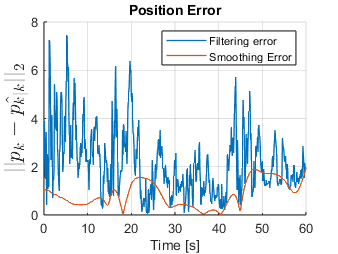



%plot error
figure();
grid on, hold on;
p7 = plot( (1:K)*T, vecnorm(xf(1:2,:)-X(1:2,2:end), 2, 1) , 'LineWidth',1,'DisplayName','Filtering error');
p8 = plot( (1:K)*T, vecnorm(xs(1:2,:)-X(1:2,2:end), 2, 1) , 'LineWidth',1,'DisplayName','Smoothing Error');
ylabel('$||p_k - \hat{p_{k|k}}||_2$', 'Interpreter','Latex', 'FontSize',16), xlabel('Time [s]')
legend([p7 p8], 'Location','northeast')
title 'Position Error'

1b

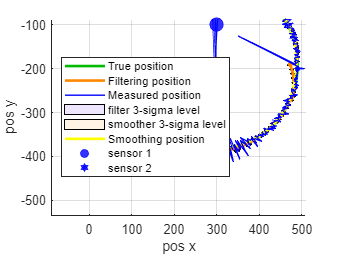


%according to previous answers, generally CKF is better.
%[xf,Pf,xp,Pp] = nonLinearKalmanFilter(Y,x_0,P_0,f,Q,h,R,'CKF');

Y(2,300) = Y(2,300)+pi/4;
[xs, Ps, xf, Pf, xp, Pp] = nonLinRTSsmoother(Y, x_0, P_0, f, Q, h, R, @sigmaPoints, 'CKF');
%follow the pdf instructions
Xm(1,:) = ( s_2(2)-s_1(2) + tan(Y(1,:))*s_1(1) - tan(Y(2,:))*s_2(1) ) ./ ( tan(Y(1,:)) - tan(Y(2,:)) );
Xm(2,:) = s_1(2) + tan(Y(1,:)) .* ( Xm(1,:) - s_1(1) );

%plot
figure();
grid on; hold on;
newcolors = {'#0B0','#F80','#FF0','#00F','#50F','#A0F','#F00'};
colororder(newcolors);
cp = get(gca,'ColorOrder');

for i=1:5:length(xf)
    ell_xy = sigmaEllipse2D(xf(1:2,i),Pf(1:2,1:2,i),3,50);
    p4 = fill(ell_xy(1,:),ell_xy(2,:), cp(5,:),'facealpha',.1, 'DisplayName','filter 3-sigma level');
end
for i=1:5:length(xs)
    ell_xy_s = sigmaEllipse2D(xs(1:2,i),Ps(1:2,1:2,i),3,50);
    p5 = fill(ell_xy_s(1,:),ell_xy_s(2,:), cp(2,:),'facealpha',.1, 'DisplayName','smoother 3-sigma level');
end
p1 = plot(X(1,:),X(2,:), 'Color', cp(1,:), 'LineWidth',2, 'DisplayName','True position');
p2 = plot(xf(1,:),xf(2,:), 'Color', cp(2,:), 'LineWidth',2, 'DisplayName','Filtering position');
p6 = plot(xs(1,:),xs(2,:), 'Color', cp(3,:), 'LineWidth',2, 'DisplayName','Smoothing position');
sc1 = scatter(s_1(1), s_1(2), 100, 'o', 'MarkerFaceAlpha',0.8, 'MarkerFaceColor', cp(4,:), 'MarkerEdgeColor', cp(4,:),'DisplayName','sensor 1');
sc2 = scatter(s_2(1), s_2(2), 200, 'h', 'MarkerFaceAlpha',0.8, 'MarkerFaceColor', cp(4,:), 'MarkerEdgeColor', cp(4,:),'DisplayName','sensor 2');

axis manual
p3 = plot(Xm(1,:),Xm(2,:), 'Color', [cp(4,:) 0.3], 'LineWidth',1, 'DisplayName','Measured position');

xlabel 'pos x', ylabel 'pos y'
legend([p1 p2 p3 p4 p5 p6 sc1 sc2], 'Location','west')

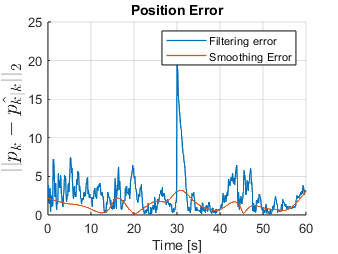



%plot error
figure();
grid on, hold on;
p7 = plot( (1:K)*T, vecnorm(xf(1:2,:)-X(1:2,2:end), 2, 1) , 'LineWidth',1,'DisplayName','Filtering error');
p8 = plot( (1:K)*T, vecnorm(xs(1:2,:)-X(1:2,2:end), 2, 1) , 'LineWidth',1,'DisplayName','Smoothing Error');
ylabel('$||p_k - \hat{p_{k|k}}||_2$', 'Interpreter','Latex', 'FontSize',16), xlabel('Time [s]')
legend([p7 p8], 'Location','northeast')
title 'Position Error'

Task2a

%initialize
A = 1.0;
Q = 1.5;
R = 3.0;
x_0 = 2;
P_0 = 8;
N = 30;
%particle numbers
N_p = 100;%canvas discussion

%genrate sequence from HA2
X = genLinearStateSequence(x_0,P_0,A,Q,N);
H = 1

H = 1

Y = genLinearMeasurementSequence(X,H,R);
%kalman filter
[xf,Pf] = kalmanFilter(Y,x_0,P_0,A,Q,H,R);
%   To use it in your filter you should first compute xf, Pf, and set
%   bResample, sigma and ax.
%   Then define a function handle
%       plotFunc_handle  = @(k, Xk, Xkmin1, Wk, j) ...
%                          (plotPostPdf(k, Xk, Wk, xf, Pf, bResample, sigma, ax))
%   Then call your PF-function with plotFunc_handle as plotFunc argument.
%plotFunc_handle  = @(k, Xk, Xkmin1, Wk, j)(plotPostPdf(k, Xk, Wk, xf, Pf, bResample, sigma, ax))
f = @(x) A*x;
h = @(x) H*x;
bResample = true;
[xfp1,Pfp1,Xp1,Wp1] = pfFilter(x_0,P_0,Y,f,Q,h,R,N_p,bResample,[]);
bResample = false;
[xfp,Pfp,Xp,Wp] = pfFilter(x_0,P_0,Y,f,Q,h,R,N_p,bResample,[]);
%MSE
mse(X(2:end)-xf)

ans = 1.4728

mse(X(2:end)-xfp1)

ans = 1.2944

mse(X(2:end)-xfp)

ans = 3.9328

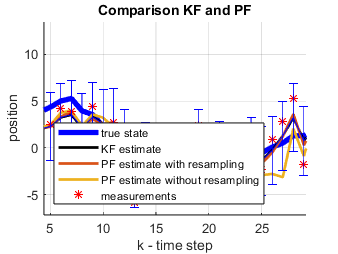


figure();
hold on, grid on;
cp = get(gca,'ColorOrder');
p1 = plot(0:N, H*X, 'b', 'LineWidth',4, 'DisplayName','true state');
p2 = plot(0:N, H*[x_0 xf],  'Color','k', 'LineWidth',2, 'DisplayName','KF estimate');
p_pfr = plot(0:N, H*[x_0 xfp1], 'Color',cp(2,:), 'LineWidth',2, 'DisplayName','PF estimate with resampling');
p_pf  = plot(0:N, H*[x_0 xfp],  'Color',cp(3,:), 'LineWidth',2, 'DisplayName','PF estimate without resampling');
p4 = plot(1:N, Y, '*r', 'DisplayName','measurements');
errorbar(0:N, H*[x_0 xf], 3*sqrt([P_0(1) squeeze(Pf(1,1,:))']), '-b', 'DisplayName','3-sigma level');
xlabel('k - time step');
ylabel('position');
legend([p1 p2 p_pfr p_pf p4],'Location','southwest');
title('Comparison KF and PF');

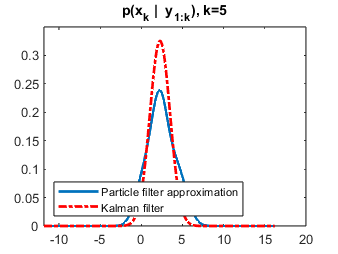

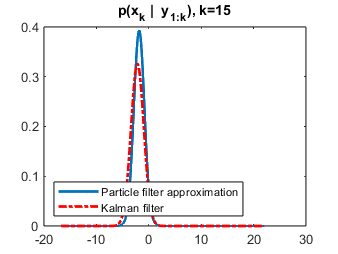

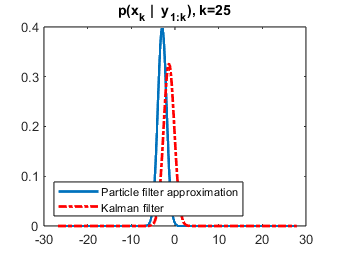




% Define the function handle
plotFunc_handle = @(k, Xk, Wk, xf, Pf, bResample, sigma, ax)(plotPostPdf(k, Xk, Wk, xf, Pf, bResample, sigma, ax));

% Set the values for plotting
bResample = false;
sigma = 1;

% Plot the posterior densities for three time instances
time_instances = [5, 15, 25];

for i = 1:length(time_instances)
    k = time_instances(i);
    Xk = Xp(:, :, k);
    Wk = Wp(:, k);
    figure();
    plotFunc_handle(k, Xk, Wk, xf, Pf, bResample, sigma, []);
end

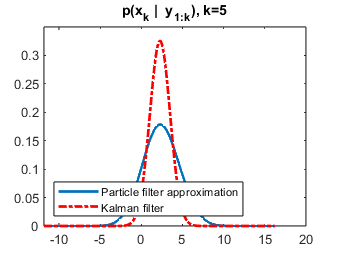

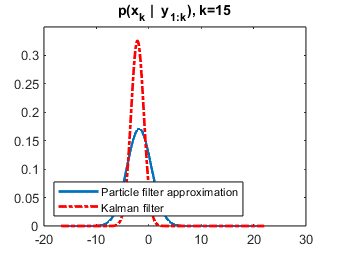

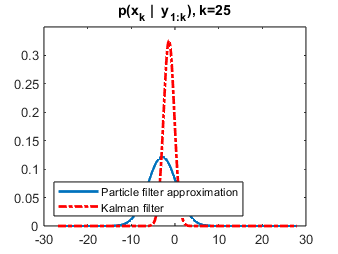

bResample = true;
for i = 1:length(time_instances)
    k = time_instances(i);
    Xk = Xp(:, :, k);
    Wk = Wp(:, k);
    figure();
    plotFunc_handle(k, Xk, Wk, xf, Pf, bResample, sigma, []);
end

Task2b

%initialize
A = 1.0;
Q = 1.5;
R = 3.0;
x_0 = 2;
P_0 = 8;
N = 30;
%particle numbers
N_p = 100;%canvas discussion

%genrate sequence from HA2
X = genLinearStateSequence(x_0,P_0,A,Q,N);
H = 1

H = 1

Y = genLinearMeasurementSequence(X,H,R);
%kalman filter
[xf,Pf] = kalmanFilter(Y,-20,2,A,Q,H,R);
%   To use it in your filter you should first compute xf, Pf, and set
%   bResample, sigma and ax.
%   Then define a function handle
%       plotFunc_handle  = @(k, Xk, Xkmin1, Wk, j) ...
%                          (plotPostPdf(k, Xk, Wk, xf, Pf, bResample, sigma, ax))
%   Then call your PF-function with plotFunc_handle as plotFunc argument.
%plotFunc_handle  = @(k, Xk, Xkmin1, Wk, j)(plotPostPdf(k, Xk, Wk, xf, Pf, bResample, sigma, ax))
f = @(x) A*x;
h = @(x) H*x;
bResample = true;
[xfp1,Pfp1,Xp1,Wp1] = pfFilter(-20,2,Y,f,Q,h,R,N_p,bResample,[]);
bResample = false;
[xfp,Pfp,Xp,Wp] = pfFilter(-20,2,Y,f,Q,h,R,N_p,bResample,[]);
%MSE
mse(X(2:end)-xf)

ans = 4.6288

mse(X(2:end)-xfp1)

ans = 8.4929

mse(X(2:end)-xfp)

ans = 145.6870

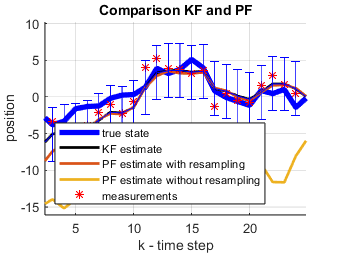


figure();
hold on, grid on;
cp = get(gca,'ColorOrder');
p1 = plot(0:N, H*X, 'b', 'LineWidth',4, 'DisplayName','true state');
p2 = plot(0:N, H*[x_0 xf],  'Color','k', 'LineWidth',2, 'DisplayName','KF estimate');
p_pfr = plot(0:N, H*[x_0 xfp1], 'Color',cp(2,:), 'LineWidth',2, 'DisplayName','PF estimate with resampling');
p_pf  = plot(0:N, H*[x_0 xfp],  'Color',cp(3,:), 'LineWidth',2, 'DisplayName','PF estimate without resampling');
p4 = plot(1:N, Y, '*r', 'DisplayName','measurements');
errorbar(0:N, H*[x_0 xf], 3*sqrt([P_0(1) squeeze(Pf(1,1,:))']), '-b', 'DisplayName','3-sigma level');
xlabel('k - time step');
ylabel('position');
legend([p1 p2 p_pfr p_pf p4],'Location','southwest');
title('Comparison KF and PF');

Task2c

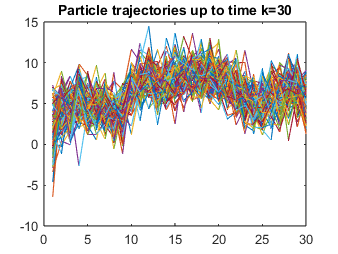

%initialize
A = 1.0;
Q = 1.5;
R = 3.0;
x_0 = 2;
P_0 = 8;
N = 30;
%particle numbers
N_p = 100;%canvas discussion

%genrate sequence from HA2
X = genLinearStateSequence(x_0,P_0,A,Q,N);
H = 1;
Y = genLinearMeasurementSequence(X,H,R);
%kalman filter
[xf,Pf] = kalmanFilter(Y,x_0,P_0,A,Q,H,R);
f = @(x) A*x;
h = @(x) H*x;
bResample = true;
[xfp,Pfp,Xp,Wp] = pfFilter(x_0,P_0,Y,f,Q,h,R,N_p,bResample,[]);

figure();
for k = 2:N
    Xk = X(:, k);          % Current state samples
    Xkmin1 = X(:, k - 1);  % Previous state samples
    
    % Plot lines between ith sample of Xk and j(i)th sample of Xk-1
    plotPartTrajs(k, Xp(:,:,k), Xp(:,:,k-1), [], 1:N_p);
end

22

%initialize
A = 1.0;
Q = 1.5;
R = 3.0;
x_0 = 2;
P_0 = 8;
N = 30;
%particle numbers
N_p = 100;%canvas discussion

%genrate sequence from HA2
X = genLinearStateSequence(x_0,P_0,A,Q,N);
H = 1

H = 1

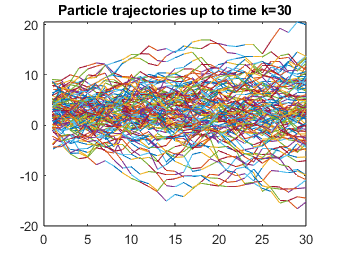

Y = genLinearMeasurementSequence(X,H,R);
%kalman filter
[xf,Pf] = kalmanFilter(Y,x_0,P_0,A,Q,H,R);
f = @(x) A*x;
h = @(x) H*x;


bResample = false;
[xfp,Pfp,Xp,Wp] = pfFilter(x_0,P_0,Y,f,Q,h,R,N_p,bResample,[]);
figure();
for k = 2:N
    Xk = X(:, k);          % Current state samples
    Xkmin1 = X(:, k - 1);  % Previous state samples
    
    % Plot lines between ith sample of Xk and j(i)th sample of Xk-1
    plotPartTrajs(k, Xp(:,:,k), Xp(:,:,k-1), [], 1:N_p);
end